dhparams = [0   	pi/2	0   	-pi/2;
             0.4318	0       0       0
            0.0203	-pi/2	0.15005	pi/2;
            0   	pi/2	0.4318	0;
            0       -pi/2	0   	0;
            0       0       0       0];

robot = rigidBodyTree;

body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
setFixedTransform(jnt1,dhparams(1,:),'dh');
body1.Joint = jnt1;
addBody(robot,body1,'base')

body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','revolute');
body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');
body5 = rigidBody('body5');
jnt5 = rigidBodyJoint('jnt5','revolute');
body6 = rigidBody('body6');
jnt6 = rigidBodyJoint('jnt6','revolute');

setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');
setFixedTransform(jnt4,dhparams(4,:),'dh');
setFixedTransform(jnt5,dhparams(5,:),'dh');
setFixedTransform(jnt6,dhparams(6,:),'dh');

body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;
body5.Joint = jnt5;
body6.Joint = jnt6;

addBody(robot,body2,'body1')
addBody(robot,body3,'body2')
addBody(robot,body4,'body3')
addBody(robot,body5,'body4')
addBody(robot,body6,'body5')


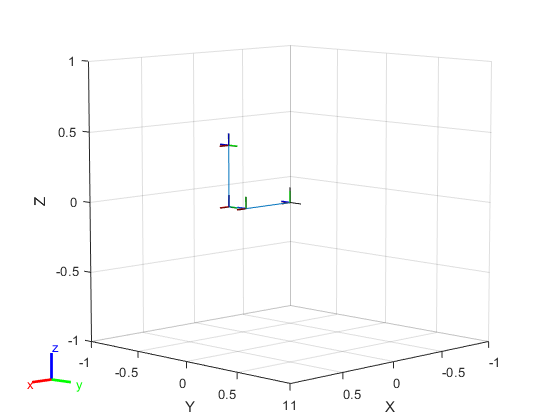

%robot = importrobot('iiwa14.urdf')
show(robot,'Visuals','on');


gripper = string(robot.BodyNames(end))

gripper = "body6"

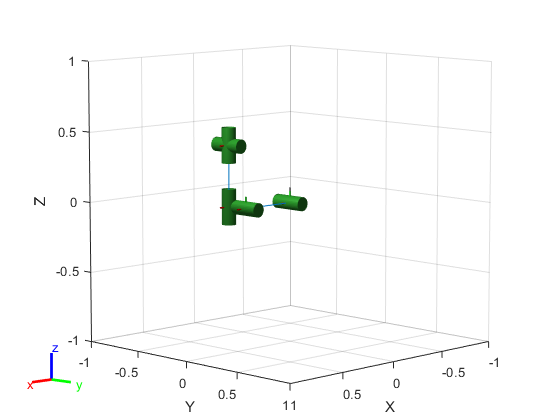

collisionObj = collisionCylinder(0.05,0.25);

for i = 1:robot.NumBodies
        addCollision(robot.Bodies{i},collisionObj)

end

show(robot,'Collisions','on','Visuals','off');

robot.DataFormat = 'row';
finalpos=[0.2 0.75 0.5];

%задача планирования
numWaypoints = 2;
%q0 = [0,pi/2,-pi/2,0,0,0];
q0 = homeConfiguration(robot)

q0 =      0     0     0     0     0     0


qWaypoints = repmat(q0, numWaypoints, 1);

%решатель
gik = generalizedInverseKinematics('RigidBodyTree', robot, ...
    'ConstraintInputs', {'cartesian','position','aiming','orientation','joint'})

gik =   generalizedInverseKinematics with properties:

      NumConstraints: 5
    ConstraintInputs: {'cartesian'  'position'  'aiming'  'orientation'  'joint'}
       RigidBodyTree: [1×1 rigidBodyTree]
     SolverAlgorithm: 'BFGSGradientProjection'
    SolverParameters: [1×1 struct]


%ограничения
heightAboveTable = constraintCartesianBounds(gripper);
heightAboveTable.Bounds = [-inf, inf; ...
                           -inf, inf; ...
                           0.05, inf]

heightAboveTable =   constraintCartesianBounds with properties:

        EndEffector: 'body6'
      ReferenceBody: ''
    TargetTransform: [4×4 double]
             Bounds: [3×2 double]
            Weights: [1 1 1]



distanceFromTarget = constraintPositionTarget(gripper);
distanceFromTarget.TargetPosition=finalpos;
%distanceFromTarget.PositionTolerance = 0.01
%приблизительно вертикальный путь размещения
alignWithZ = constraintAiming(gripper);
alignWithZ.TargetPoint = [0, 0, 100]

alignWithZ =   constraintAiming with properties:

         EndEffector: 'body6'
       ReferenceBody: ''
         TargetPoint: [0 0 100]
    AngularTolerance: 0
             Weights: 1


%граничение границ положени
limitJointChange = constraintJointBounds(robot)

limitJointChange =   constraintJointBounds with properties:

     Bounds: [6×2 double]
    Weights: [1 1 1 1 1 1]


fixOrientation = constraintOrientationTarget(gripper);
fixOrientation.OrientationTolerance = deg2rad(1)

fixOrientation =   constraintOrientationTarget with properties:

             EndEffector: 'body6'
           ReferenceBody: ''
       TargetOrientation: [1 0 0 0]
    OrientationTolerance: 0.0175
                 Weights: 1




limitJointChange.Weights = zeros(size(limitJointChange.Weights));
fixOrientation.Weights = 0;

[qWaypoints(2,:),solutionInfo] = gik(q0, heightAboveTable, ...
                       distanceFromTarget, alignWithZ, fixOrientation, ...
                       limitJointChange);

alignWithZ.Weights = 0;
fixOrientation.TargetOrientation = ...
    tform2quat(getTransform(robot,qWaypoints(2,:),gripper));


framerate = 15;
r = rateControl(framerate);
tFinal = 10;
tWaypoints = [0,linspace(tFinal/2,tFinal,size(qWaypoints,1)-1)];
numFrames = tFinal*framerate;
qInterp = pchip(tWaypoints,qWaypoints',linspace(0,tFinal,numFrames))';
gripperPosition = zeros(numFrames,3);

for k = 1:numFrames
    gripperPosition(k,:) = tform2trvec(getTransform(robot,qInterp(k,:),gripper));
end

figure;
show(robot, qWaypoints(1,:), 'PreservePlot', false);
hold on
p = plot3(gripperPosition(1,1), gripperPosition(1,2), gripperPosition(1,3));


hold on
p = plot3(gripperPosition(1,1), gripperPosition(1,2), gripperPosition(1,3));
axis([-0.5,1,-0.5,1,-0.5,1])
for k = 1:size(qInterp,1)
    show(robot, qInterp(k,:), 'PreservePlot', false);
    p.XData(k) = gripperPosition(k,1);
    p.YData(k) = gripperPosition(k,2);
    p.ZData(k) = gripperPosition(k,3);
    waitfor(r);
end

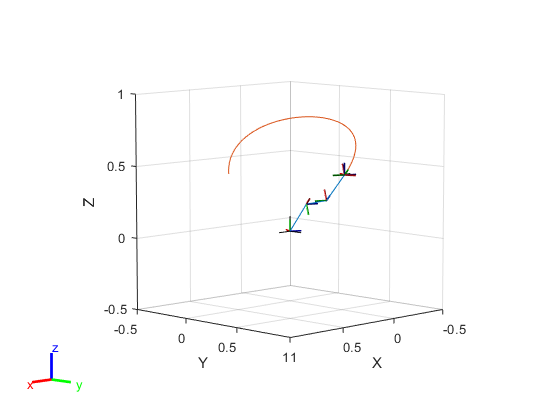

hold off